# plotLookupTable1DBlocks sample script

model_name = "plotLookupTable1DBlocks_SampleModel_refsub";
assert(isfile(which(model_name)))
load_system(model_name)

By default, all lookup table 1D blocks in the specified subsystem path are visualized.

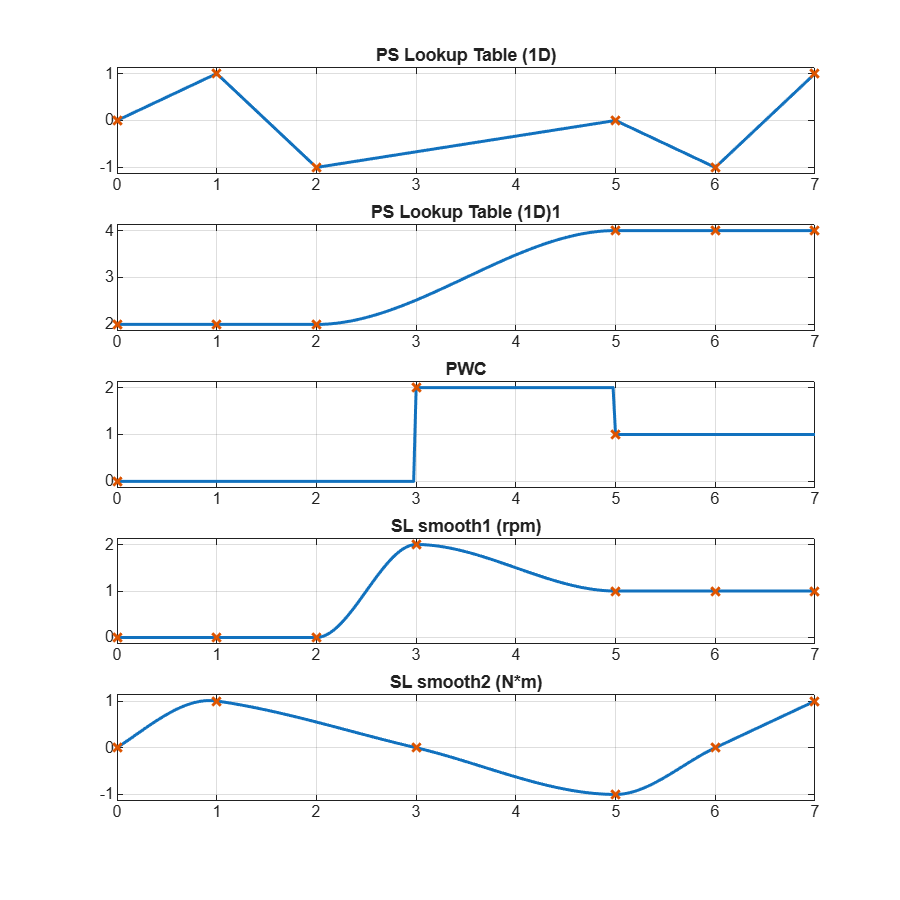

mus1.ModelUtil.plotLookupTable1DBlocks(model_name)

Use the `Blocks` option to specify the blocks for visualization.

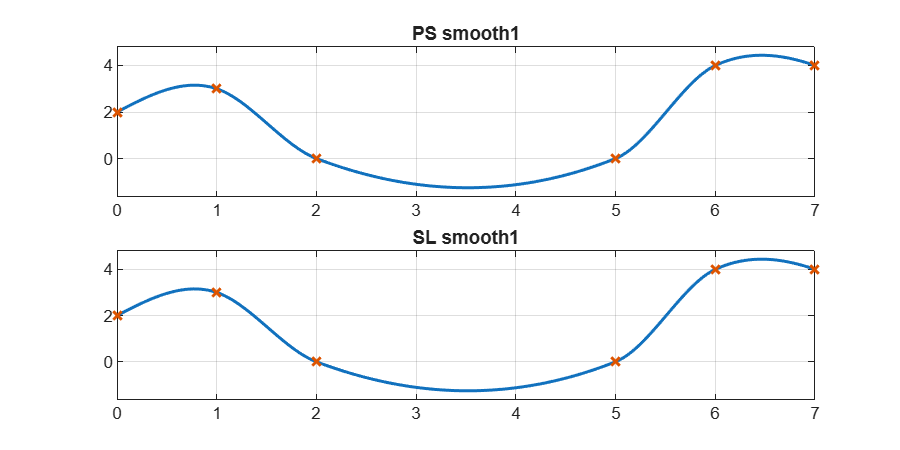

fig = figure;
fig.Position(3:4) = [600 300];  % width height
mus1.ModelUtil.plotLookupTable1DBlocks(model_name+"/Subsystem", Blocks=["PS smooth1" "SL smooth1"], ParentAxes=axes(fig))

Use the `SearchDepth` option to specify how many layers to search lookup table 1D blocks.

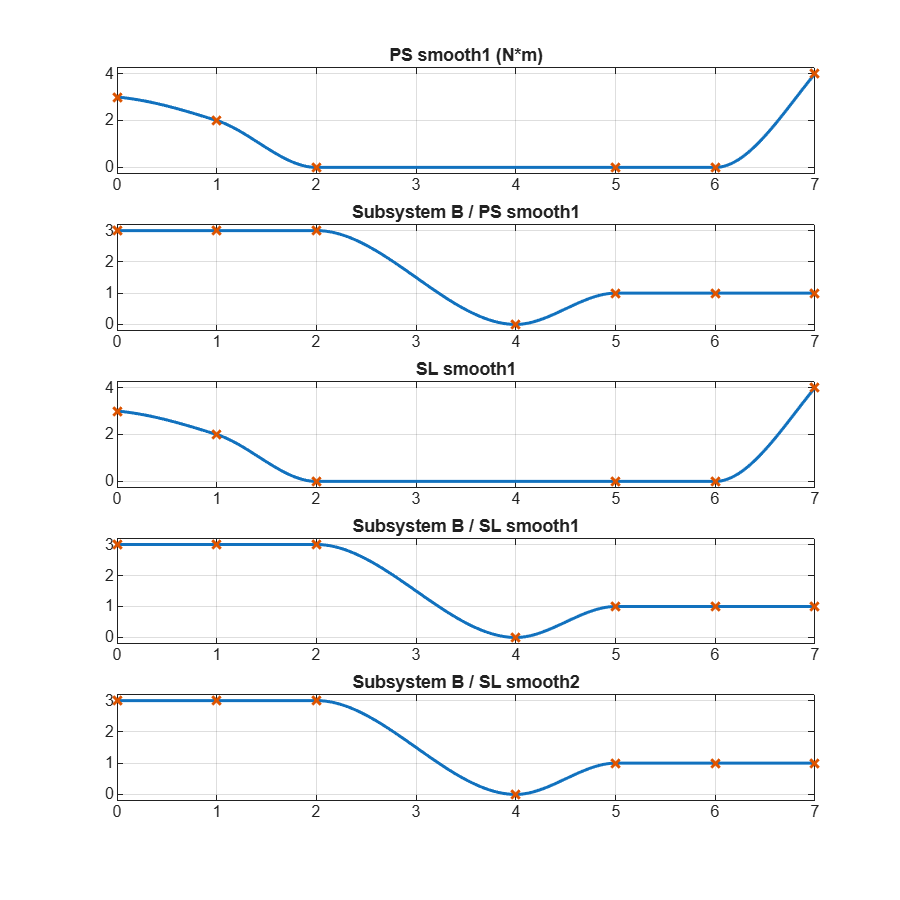

mus1.ModelUtil.plotLookupTable1DBlocks(model_name+"/Subsystem/Subsystem A", SearchDepth=2)

*Copyright 2025-2026 The MathWorks, Inc.*